# Questão 11.7

1. Malha aberta

s = tf('s');

Gp = 4500/(s*(s+361.2));
zpk(Gp)

ans =
 
     4500
  -----------
  s (s+361.2)
 
Continuous-time zero/pole/gain model.
Model Properties


T = 0.001;

Gpz = c2d(Gp, T, 'zoh')

Gpz =
 
  0.002002 z + 0.001775
  ----------------------
  z^2 - 1.697 z + 0.6968
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties


zpk(Gpz)

ans =
 
  0.0020019 (z+0.8867)
  --------------------
    (z-1) (z-0.6968)
 
Sample time: 0.001 seconds
Discrete-time zero/pole/gain model.
Model Properties


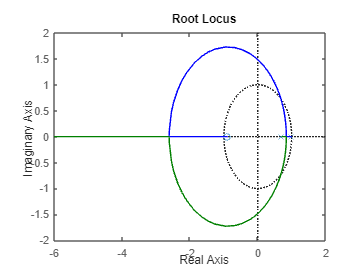

rlocus(Gpz);

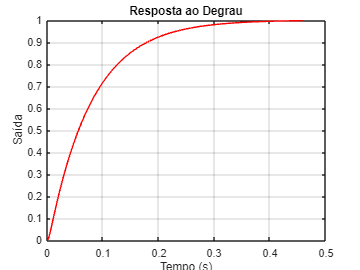


[y, tOut] = step(feedback(Gpz, 1));
plot(tOut, y, color='red');
xlabel('Tempo (s)');
ylabel('Saída');
title('Resposta ao Degrau');
grid on;

2. Controlador

K = 80.28;

Tz = feedback(Gpz * K, 1)

Tz =
 
    0.1607 z + 0.1425
  ----------------------
  z^2 - 1.536 z + 0.8393
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties


pole(Tz)

ans =    0.7681 + 0.4994i
   0.7681 - 0.4994i


zero(Tz)

ans = -0.8867

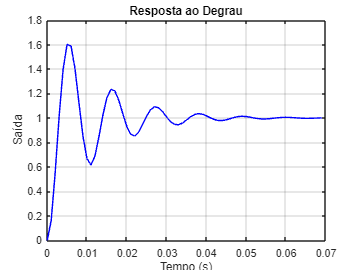



[y, tOut] = step(Tz);
plot(tOut, y, color='blue');
xlabel('Tempo (s)');
ylabel('Saída');
title('Resposta ao Degrau');
grid on;


ess = 1 - y(end);  % Erro em regime permanente
fprintf('Erro em regime permanente: %.6f\n', ess);

Erro em regime permanente: -0.000866


fprintf('yf: %.6f\n', y(end));

yf: 1.000866



% Obtém informações da resposta ao degrau
info = stepinfo(y, tOut);

% Tempo de acomodação a 2%
tempo_acomodacao = info.SettlingTime;

% Ultrapassagem percentual
ultrapassagem = info.Overshoot;

% Exibe os resultados no console
fprintf('Tempo de acomodação a 2%%: %.4f s\n', tempo_acomodacao);

Tempo de acomodação a 2%: 0.0444 s


fprintf('Ultrapassagem percentual: %.2f%%\n', ultrapassagem);

Ultrapassagem percentual: 59.90%


2. Controlador

z = tf('z');

K = 1

K = 1

Gcz = (K*(z+0.1))/(z-0.1);
zpk(Gcz)

ans =
 
  (z+0.1)
  -------
  (z-0.1)
 
Sample time: unspecified
Discrete-time zero/pole/gain model.
Model Properties



FT_cl = feedback(Gpz * Gcz, 1);
FT_cl_zpk = zpk(FT_cl)

FT_cl_zpk =
 
    0.0020019 (z+0.8867) (z+0.1)
  --------------------------------
  (z-0.984) (z-0.7116) (z-0.09927)
 
Sample time: 0.001 seconds
Discrete-time zero/pole/gain model.
Model Properties


pole(FT_cl_zpk)

ans =     0.9840
    0.7116
    0.0993


zero(FT_cl_zpk)

ans =    -0.8867
   -0.1000


[y, tOut] = step(FT_cl);
plot(tOut, y, color='yellow');
xlabel('Tempo (s)');
ylabel('Saída');
title('Resposta ao Degrau');
grid on;